**Quadratic Function:** $f(x) = x_1^2 + \beta x_2^2$

**Bean Function:** $f(x) = (1-x_1)^2 + (1-x_2)^2 + \frac{1}{2}(2x_2 - x_1^2)^2$

**Spring System:** $f(x) = \frac{1}{2}k_1\left(\sqrt{(l_1+x_1)^2 + x_2^2} - l_1\right)^2 + \frac{1}{2}k_2\left(\sqrt{(l_2-x_1)^2 + x_2^2}  - l_2\right)^2 - mgx_2$


beta = 4;
system = 3;

syms x1 x2 

switch system 
    case 1
        % Quadratic function
        fobj=@(x) (x(1)).^2 + beta*x(2).^2; 
        gradobj=@(x) 2*[x(1), (beta*x(2))];
        f = @(x1, x2) x1.^2 + beta*x2.^2;
        x0=[10 1];
        xc1 = -5:0.1:12; xc2 = -7:0.1:7;
    case 2
        % The bean functon
        f = @(x1, x2) (1-x1).^2 + (1-x2).^2 + (0.5)*(2*x2 - x1.^2).^2
        fobj = @(x) (1-x(1)).^2 + (1-x(2)).^2 + (0.5)*(2*x(2) - x(1).^2).^2;
        x0 = [-1.2 2];
        xc1 = -3:0.1:3; xc2 = -1:0.1:3;
    case 3
        % Spring system 
        l1 = 12; l2 = 8; k1 = 1; k2 = 10; mg = 7;
        f = @(x1, x2) (1/2)*k1*(sqrt( (l1+x1).^2 + x2.^2) - l1).^2 + ...
            (1/2)*k2*(sqrt((l2-x1).^2 + x2.^2) - l2).^2 - mg*x2;
        fobj = @(x) (1/2)*k1*(sqrt( (l1+x(1)).^2 + x(2).^2) - l1).^2 + ...
            (1/2)*k2*(sqrt((l2-x(1)).^2 + x(2).^2) - l2).^2 - mg*x(2);
        x0 = [9, -2];
        xc1 = -3:0.1:17; xc2 = -10:0.1:12;
    otherwise
end



gf = matlabFunction(gradient(f(x1,x2),[x1,x2]));

N = 2000;
X = zeros(N,2); EG = 1e-10; EA = 1e-10; ER = 1e-10;
th0 = 1e-5;


X(1,:) = x0;
for k = 2:N
    % first criteria
    if norm(gf(x0(1), x0(2))) <= EG
        break;
    end
    % traspose to make a column vector
    linedir = (-gf(x0(1), x0(2)))';%/norm((gf(x0(1), x0(2)))); %-gradobj(x0);
    
    % line search section
    fline = @(alpha) fobj(x0 + alpha*linedir);
    [a,b] = bracket_minimumsp(fline);
    alpha = fminbnd(fline,a, b);
     
    % new point
    x0 = x0 + alpha*linedir;
    X(k,:) = x0;

    % check second criteria
    nX = abs(fobj(X(k,:)) - fobj(X(k-1,:)));
    if  nX < EA + ER * abs(fobj(X(k-1,:)))
        break;
    end
end
X = X(1:k-1,:);
fprintf("Using %d iteration", k-2);

Using 20 iteration

fprintf("Optimal solution x=%f,%f\n",X(end-1,:));

Optimal solution x=2.785175,6.899635


fprintf("Optimal value f(x)= %d \n",fobj(X(end-1,:)));

Optimal value f(x)= -3.688043e+01 


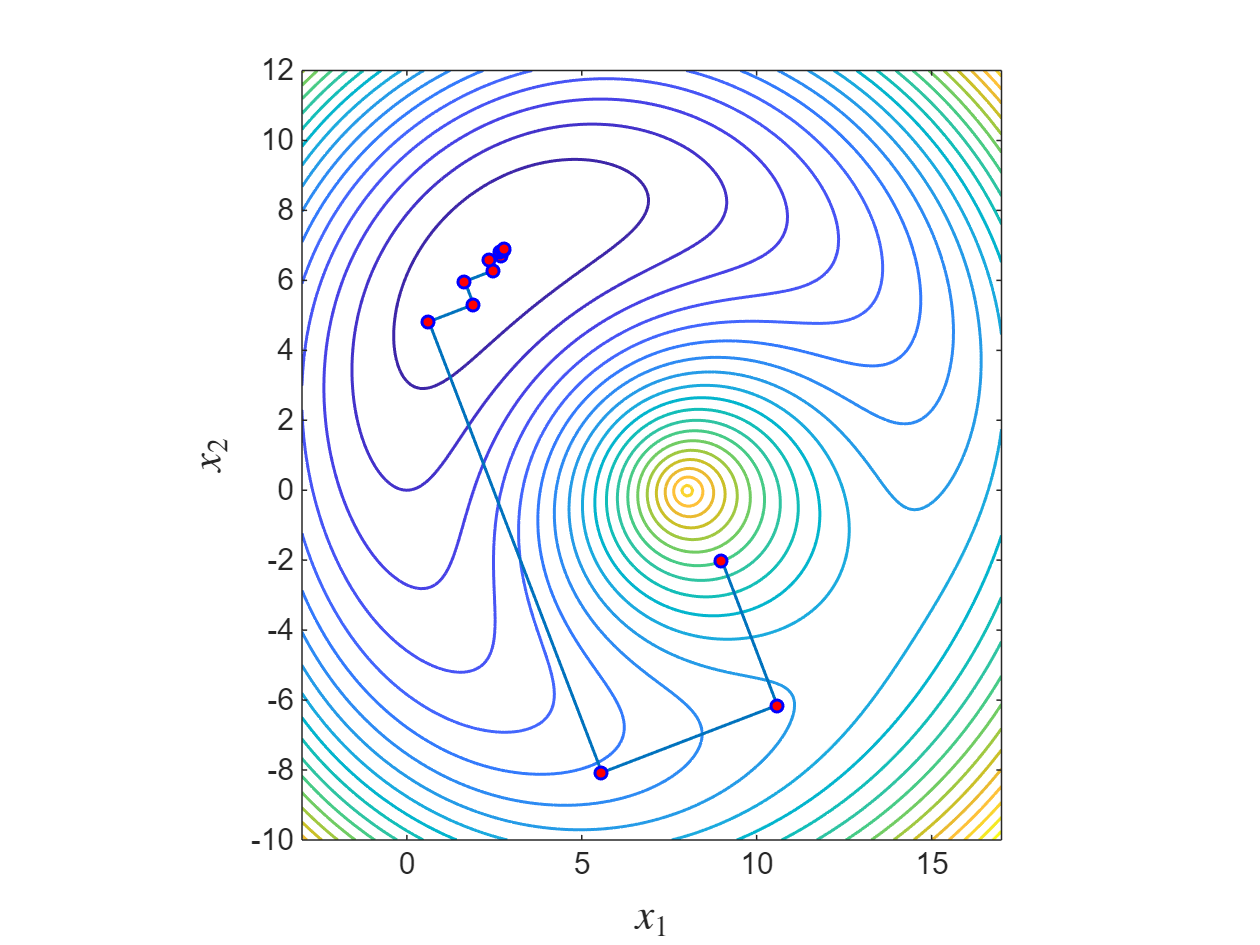

[Xc,Yc] = meshgrid(xc1,xc2);
Zc = f(Xc,Yc);

switch system 
    case 1
        contour(Xc,Yc,Zc, -100:40:800, 'LineWidth',1);
    case 2
        contour(Xc,Yc,Zc, -500:2:100, 'LineWidth',1);
    case 3
        contour(Xc,Yc,Zc, -100:20:400, 'LineWidth',1);
    otherwise
end

xlabel("$x_1$",'Interpreter','latex',FontSize=14);
ylabel("$x_2$","FontSize",14,'Interpreter','latex')
hold on;
    plot(X(:,1), X(:,2), '-o','linewidth', 1,...
        'MarkerFaceColor','red', 'MarkerEdgeColor','blue',...
        'markersize', 4)
    axis equal
hold off;

X

X =     9.0000   -2.0000
   10.5881   -6.1491
    5.5750   -8.0724
    0.6292    4.8192
    1.9084    5.3100
    1.6556    5.9690
    2.4769    6.2839
    2.3619    6.5839
    2.7003    6.7137
    2.6626    6.8119


f(X(1,end), X(2,end))

ans = 112.9909